%Using the Matlab Symbolic Toolbox to solve for properties of parametric
%curves
clc, clear all

%For this demo code, we will solve for the parametric circle that is
%presented in Robo Night 1

%First we must define the symbolic variables we will being using
syms R u r

Operation terminated by user during sym>symr (line 1380)


In sym>numeric2cellstr (line 1321)
                S{k} = symr(double(x(k)));

In sym>tomupad (


%Define the equation for the parametric circle. For clarity, I am first 
%creating individual equations for r in the i, j, and k direction, 
%then packing them in one vector. In this case, we are
%creating a 1x3 vector that has symbolic equations for the i, j, and k
%components of the equation, respectively. Note that the k component in
%this case is just equal to 0. We use 0*u because if we substitute a vector
%of numerical values in for the symbolic u at a later time, the dimensions
%of the vector will be consistent.
ri=4*(0.3960*cos(2.65*(u+1.4)));
rj=4*(-0.99*sin(u+1.4));
rk=0*u;
r=[ri,rj,rk];

%to take the derivative, we use the diff function in Matlab, with the
%inputs being diff(function,variable to differentiate)
dr=diff(r,u);

%you will see that the unit tangent vector is a
%bit difficult to read and the algebra doesn't seem to be simplified
%(note I use the norm function, not abs)
T_hat_ugly=dr./norm(dr)

$$T\_hat\_ugly = \begin{array}{l} \left(\begin{array}{ccc} -\frac{5247\,\sin\left(\frac{53\,u}{20}+\frac{371}{100}\right)}{1250\,\sigma_{1}} & -\frac{99\,\cos\left(u+\frac{7}{5}\right)}{25\,\sigma_{1}} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{\frac{27531009\,{\left|\sin\left(\frac{53\,u}{20}+\frac{371}{100}\right)\right|}^{2}}{1562500}+\frac{9801\,{\left|\cos\left(u+\frac{7}{5}\right)\right|}^{2}}{625}} \end{array}$$


% we want to add some assumptions so that the algebra simplifies the way it
% should
assume(R,'positive') % radius should be positive
assume(u,'real') % parameter u should be real

%now we can use the simplify function to make things look nice
T_hat=simplify(T_hat_ugly)

$$T\_hat = \begin{array}{l} \left(\begin{array}{ccc} -\frac{53\,\sin\left(\frac{53\,u}{20}+\frac{371}{100}\right)}{\sigma_{1}} & -\frac{50\,\cos\left(u+\frac{7}{5}\right)}{\sigma_{1}} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{2500\,{\cos\left(u+\frac{7}{5}\right)}^{2}+2809\,{\sin\left(\frac{53\,u}{20}+\frac{371}{100}\right)}^{2}} \end{array}$$


%Next, we want to find the unit normal vector
dT_hat=diff(T_hat,u);
N_hat=dT_hat/norm(dT_hat);
N_hat=simplify(N_hat)

%The unit binormal vector is found from the cross product of the unit
%tangent and unit normal
B_hat=cross(T_hat,N_hat);
B_hat=simplify(B_hat)

%We can also find the curvature
%kappa=norm(dT_hat)/norm(dr);
%kappa=simplify(kappa)

%How about the Torsion?
%tau=-dot(N_hat,(diff(B_hat,u)/norm(dr)))

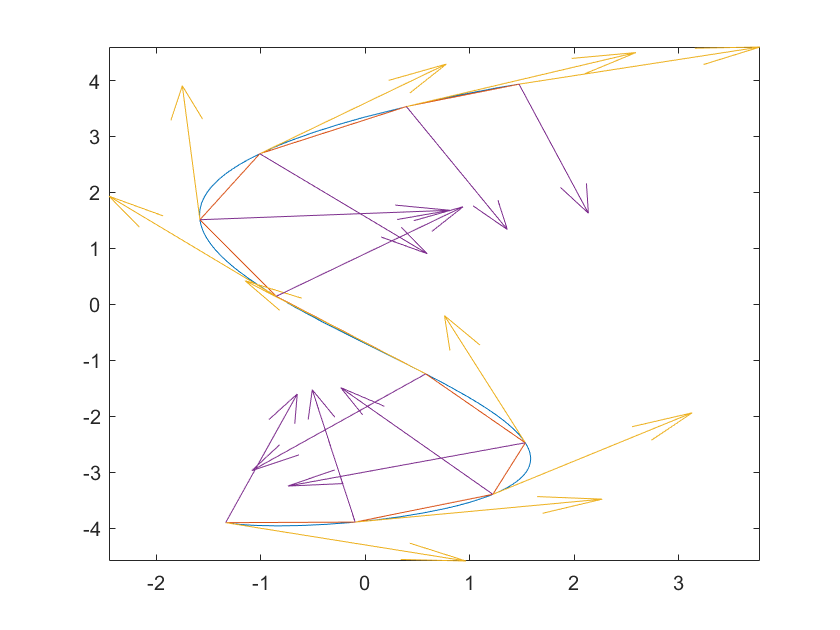

% Plot parametric curve
u_points = linspace(0,3.2,10);
T_hat_values = subs(T_hat',u,u_points);
N_hat_values = subs(N_hat',u,u_points);
xy_points = subs(r',u,u_points);

clf
fplot(ri,rj,[0,3.2])
hold on
plot((xy_points(1,:))',(xy_points(2,:)'))
quiver((xy_points(1,:))',(xy_points(2,:)'),(T_hat_values(1,:))',(T_hat_values(2,:))');
quiver((xy_points(1,:))',(xy_points(2,:)'),(N_hat_values(1,:))',(N_hat_values(2,:))');